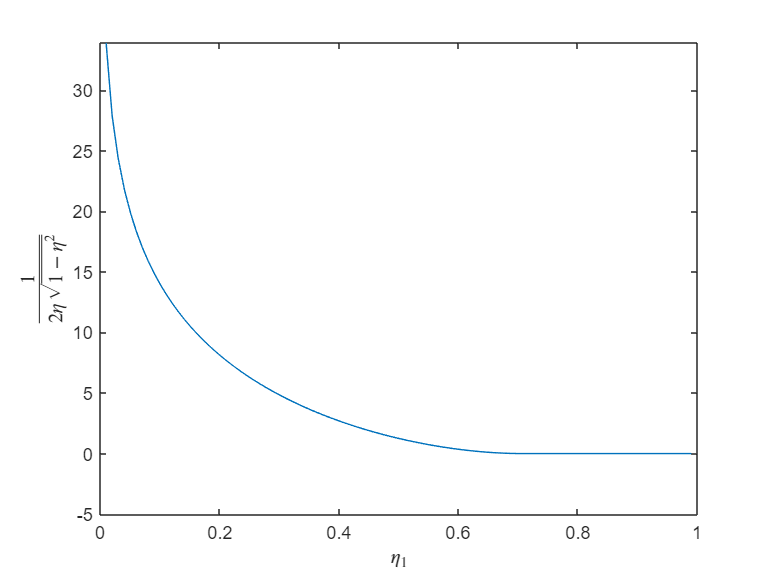

clear all;
close all;
clc;
Num=100;

eta = linspace(0,1,Num);
Mr = zeros(Num,1);

for i=1:Num
Mr(i) = 1/(2*eta(i)*sqrt(1-(eta(i))^2))*((eta(i)>0) &&(eta(i)<=sqrt(2)/2))...
        +1*((eta(i)<1) &&(eta(i)>sqrt(2)/2));
Mr(i) = 20*log10(Mr(i));
end

plot(eta,Mr);
axis([0,1,-5,max(Mr)]); hx= xlabel('$\eta$'); set(hx,'Interpreter','latex');  hy= ylabel('$\frac{1}{2\eta\sqrt{1-\eta^2}}$'); set(hy,'Interpreter','latex'); 